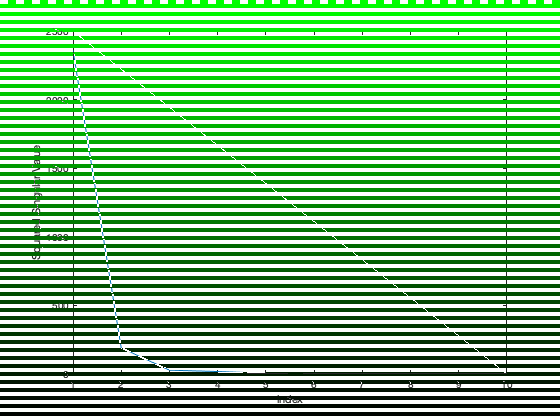

X = importdata('./data_problem4/data1/data1.mat');
tau = 150;
[~,sigma,~] = svd(X);
[m,n] = size(sigma);
for i = 1:n
    sigma(i,i) = sigma(i,i)^2;
end
squared_sigma = [];

for i = 1:n
    squared_sigma = [squared_sigma, sigma(i,i)];
end
sum_squared_sigama = sum(squared_sigma);
clf;
plot(squared_sigma);xlabel('index');ylabel('Squared Singular Value');

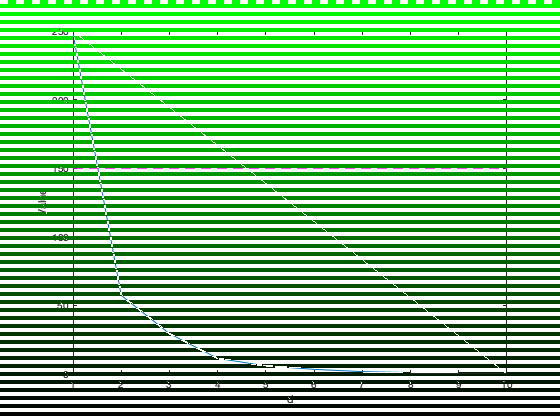

for i = 1:n-1
    squared_sigma(i) = sum(squared_sigma(i+1:n));
end
clf;
plot(squared_sigma);
hold on;
plot([1,n],[tau,tau],'m--');xlabel('d');ylabel('Value');

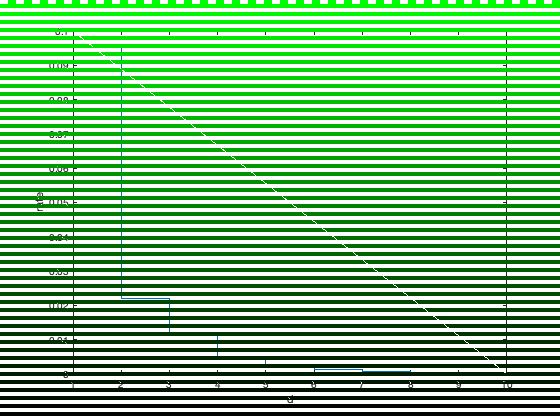

clf;
f_d = [];
for i = 1:n
    temp = squared_sigma(i)/sum_squared_sigama;
    f_d = [f_d, temp];
end
stairs(f_d);xlabel('d');ylabel('rate');

[D,N] = size(X);
1 * (D+N+1)/(D*N)

ans = 0.1005

2 * (D+N+1)/(D*N)

ans = 0.2011

3 * (D+N+1)/(D*N)

ans = 0.3016

4 * (D+N+1)/(D*N)

ans = 0.4022